clear all;
L = 0.127; %m
y_min = -2*L;
y_max = 2*L;

x_min = 0;
x_max = 2*L;

delta = 0.001;

v_x = x_min:delta:x_max;
v_y = y_min:delta:y_max;


n_x = size(v_x,2);
n_y = size(v_y,2);


[m_x,m_y] = meshgrid(v_x,v_y);
M11 = zeros(n_y,n_x);
M12 = M11;
M22 = M11;
M21 = M11;

for  i = 1:n_x
    for j = 1:n_y
        [M11(j,i),M12(j,i),M21(j,i),M22(j,i),~] = mass_jacobian(v_x(i), v_y(j),false);
    end
end

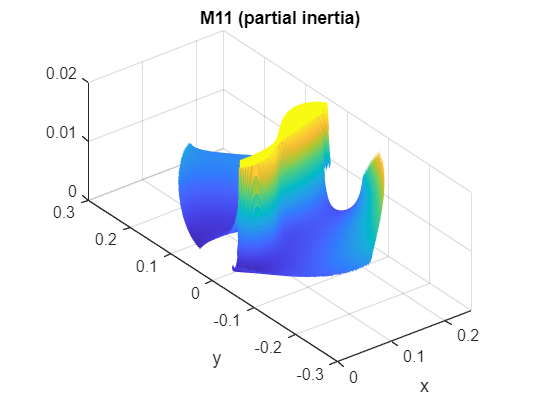


figure;
surf(m_x,m_y,M11,"EdgeColor","none");
title("M11 (partial inertia)");
xlabel("x")
ylabel("y")
% zlim([0 21.7])
daspect([1 1 0.1])

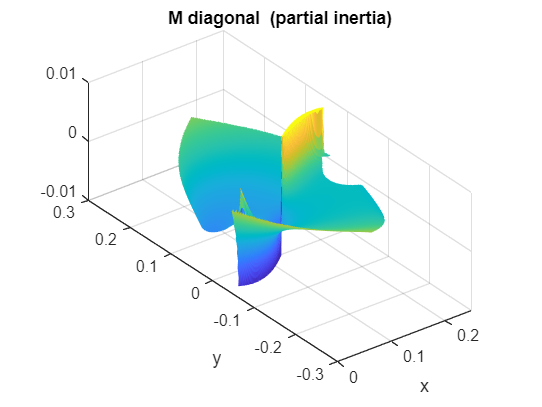


figure;
surf(m_x,m_y,M12,"EdgeColor","none");
title("M diagonal  (partial inertia)");
xlabel("x")
ylabel("y")

daspect([1 1 0.1])

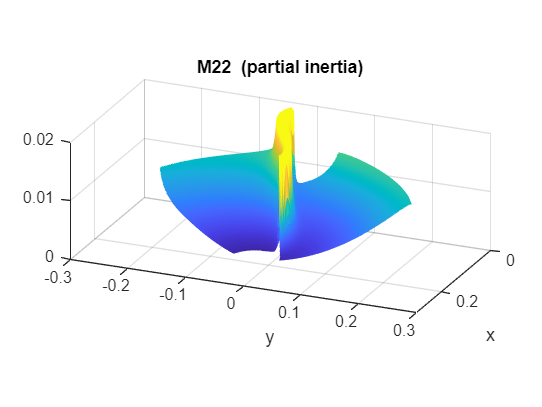

% zlim([-0.05 0.05])


figure;
surf(m_x,m_y,M22,"EdgeColor","none");
title("M22  (partial inertia)");
xlabel("x")
ylabel("y")

daspect([1 1 0.1])
view([-246.8184 21.0939])

% zlim([0 21.7])